# 3D plotting in MATLAB

## * different dimention plots

% line graphs
help plot3
help contour3
help contourslice
help ezplot3
help waterfall

% mesh graphs and Bar Graphs
help mesh
help meshc
help meshz
help ezmesh
help stem3
help bar3
help bar3h

% are graphs and constructive objects
help pie3
help fill3
help patch
help cylinder
help ellipsoid
help sphere

% surface graphs
help surf
help surf1
help surfc
help ezsurf
help ezsurfc

% direction graphs
help quiver3
help comet3
help streamslices

% volumetric graphs
help scatter3
help coneplot
help streamline
help streamribbon
help streamtube

## * plotting points and lines

clear all, close all
t = linspace(1,40,200);
x = randi([-5,5],200,1)

x =     -1
    -5
    -5
     5
    -4
     5
    -3
    -5
     2
    -5


y = x*10

y =    -10
   -50
   -50
    50
   -40
    50
   -30
   -50
    20
   -50


% y = randi([-50,50],200,1)
z = x + y

z =    -11
   -55
   -55
    55
   -44
    55
   -33
   -55
    22
   -55


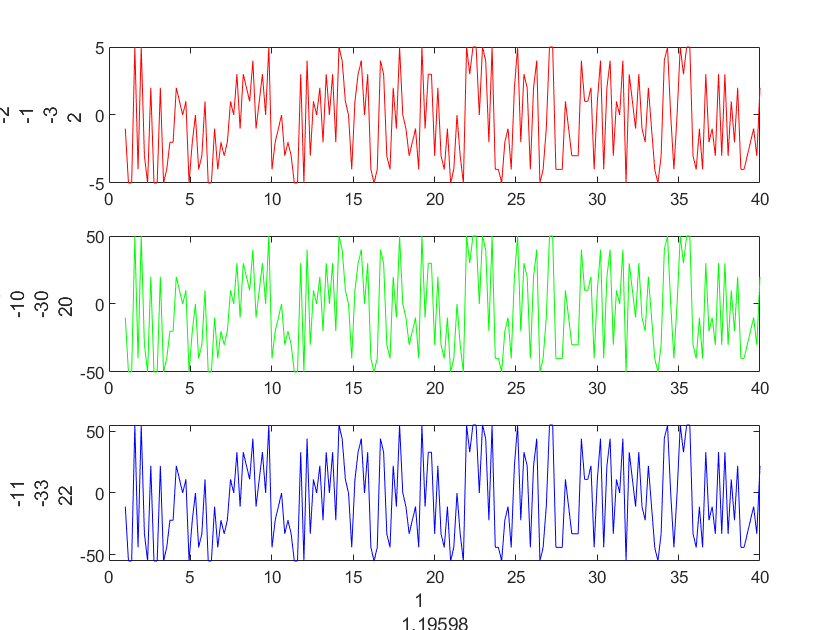

% z = randi([0,50],200,1)

subplot(3,1,1)
plot(t,x,'r') %plot x as a red line
ylabel(x)
subplot(3,1,2)
plot(t,y,'g') %plot y as a green line
ylabel(y)
subplot(3,1,3)
plot(t,z,'b') %plot z as a blue line
ylabel(z)
xlabel(t)

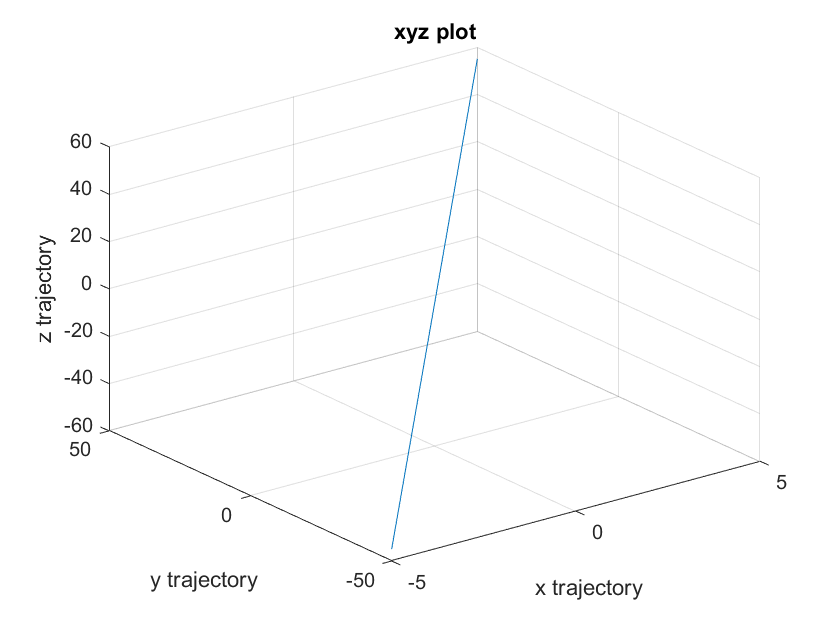

figure
plot3(x,y,z) %plot trajectories together in 3D
xlabel('x trajectory') %label the x-axis
ylabel('y trajectory') %label the y-axis
zlabel('z trajectory') %label the z-axis
title('xyz plot')
set(gca,'xgrid','on','ygrid','on','zgrid','on') %plot grids
set(gca,'cameraposition',[200 -200 200]); %change the orientation

## * surface plots

clear all, close all
x = [4.0 0.5 2.0 0.3 1.2 1.2 0.4 2.2 2.1 2.1 3.1 3.1 4.1 4.5 3.6 5.5 6.0 6.2 6.2 6.2 6.3 6.2 5.6 3.6 4.5 2.5 2.3 1.5 4.5 4.5 5.3 3.5 4.4 3.4 4.8]
y = [4.0 6.0 5.2 0.3 0.0 0.5 1.0 0.2 0.5 1.1 0.2 1.2 1.2 1.8 2.1 0.5 1.0 1.1 6.1 5.3 4.5 3.4 2.4 2.4 3.2 3.5 3.4 3.5 5.3 5.6 4.3 5.5 6.0 1.8 3.5]
z = [10 2.0 1.2 5.0 1.0 1.0 6.0 1.0 1.0 1.1 7.0 1.2 1.2 1.8 5.1 1.0 7.0 1.1 1.1 6.3 1.5 1.4 7.4 1.4 1.2 1.5 8.4 1.5 1.3 9.6 1.3 1.5 1.0 8.0 1.5]
xi=[0:0.25:6.5]; %equally spaced row vector of x positions
yi=[0:0.25:6.5]; %equally spaced column vector of y positions
[xi_grid,yi_grid]=meshgrid(xi,yi);
zi_grid=griddata(x,y,z,xi_grid,yi_grid); %interpolate the z data
h=surf(xi_grid,yi_grid,zi_grid) %create a surface plot
hold on %add to the plot
hs = plot3(x,y,z,'ok','markerfacecolor','k') %original data points
set(h,'facealpha',0.5) %surface is semitransparent
xlabel('x') %label the x-axis
ylabel('y') %label the y-axis
zlabel('Height') %label the z-axis
set(gca,'cameraposition',[-21.5 44.2 2691]) %rotate the plot
colorbar %add a colorbar

colormap gray

## * Overlaying images

%read image file from internet
clear all, close all
filename = 'https://upload.wikimedia.org/wikipedia/commons/c/cd/Land_ocean_ice_2048.jpg'
cdata = imread(filename); %read the image from the given location
size(cdata) %size of the image data

[x, y, z] = sphere(72); %generate data points on a sphere
figure %open a new figure window
h = surf(x,y,z) %plot a surface from the sphere data
axis vis3d %set the axis perspective suitable for 3D

set(h, 'facecolor', 'texturemap') %prepare the panels to be colored
set(h,'cdata', cdata); %color the panels with the jpg data
set(h,'edgecolor', 'none'); %remove lines between panels
set(gca,'visible','off'); %hide the axes box
set(gcf,'color',[0 0 0]); %set the background color to black

## * Plotting elevation data

## Step 1: Reading a csv file

% using readtable function
clear all
close all
format long %use this to avoid losing precision
T = readtable('Copy_of_WGS84_commaSV.csv');
Lon = table2array(T(:,1))

Lon = 	1.0e+02 *

   1.157398095404170
   1.157398076618905
   1.157398086114966
   1.157398116731885
   1.157398049066525
   1.157398058249828
   1.157398067433130
   1.157398088865509
   1.157398098048812
   1.157398106817165


Lat = table2array(T(:,2))

Lat =  -32.049151906515959
 -32.049149867184134
 -32.049150904994448
 -32.049150078459441
 -32.049146880974511
 -32.049147882390777
 -32.049148883807014
 -32.049147064875378
 -32.049148066291593
 -32.049149004149783


Depth = table2array(T(:,3))

Depth =  -13.833000000000000
 -13.827000000000000
 -13.821999999999999
 -13.847000000000000
 -13.760999999999999
 -13.779999999999999
 -13.802000000000000
 -13.804000000000000
 -13.826000000000001
 -13.887000000000000


Ele = -Depth

Ele =   13.833000000000000
  13.827000000000000
  13.821999999999999
  13.847000000000000
  13.760999999999999
  13.779999999999999
  13.802000000000000
  13.804000000000000
  13.826000000000001
  13.887000000000000


%Generate grid
X = [min(Lon):0.000001:max(Lon)];
Y = [min(Lat):0.000001:max(Lat)];
%make regular grid using meshgrid
[Xgrid,Ygrid] = meshgrid(X,Y)

Xgrid = 	1.0e+02 *

   1.157397617812837   1.157397627812837   1.157397637812837   1.157397647812837   1.157397657812837   1.157397667812837   1.157397677812837   1.157397687812837   1.157397697812837   1.157397707812837   1.157397717812837   1.157397727812837   1.157397737812837   1.157397747812837   1.157397757812837   1.157397767812837   1.157397777812837   1.157397787812837   1.157397797812837   1.157397807812837   1.157397817812837   1.157397827812837   1.157397837812837   1.157397847812837   1.157397857812837   1.157397867812837   1.157397877812837   1.157397887812837   1.157397897812837   1.157397907812837   1.157397917812837   1.157397927812837   1.157397937812837   1.157397947812837   1.157397957812837   1.157397967812837   1.157397977812837   1.157397987812837   1.157397997812837   1.157398007812837   1.157398017812837   1.157398027812837   1.157398037812837   1.157398047812837   1.157398057812837   1.157398067812837   1.157398077812837   1.157398087812837   1.157398097812837

Ygrid =  -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.049151906515959 -32.0491519

topo = griddata(Lon,Lat,Ele,Xgrid,Ygrid)

topo =                  NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN             

bath = griddata(Lon,Lat,Depth,Xgrid,Ygrid)

bath =                  NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN             

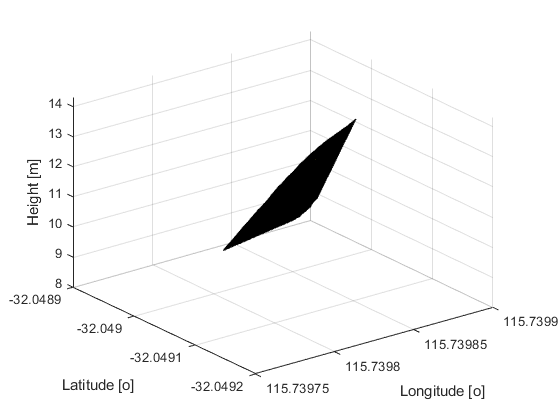

% plot topographic surface
figure %create a new figure window
surf(Xgrid,Ygrid,topo) %plot the data grids as a surface
xlabel('Longitude [o]') %add a x-axis label
ylabel('Latitude [o]') %add a y-axis label
zlabel('Height [m]') %add a z-axis label

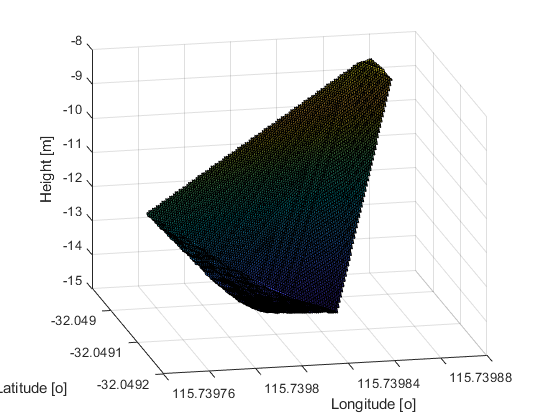

% plot bathy surface
figure %create a new figure window
surf(Xgrid,Ygrid,bath) %plot the data grids as a surface
xlabel('Longitude [o]') %add a x-axis label
ylabel('Latitude [o]') %add a y-axis label
zlabel('Height [m]') %add a z-axis label